% Short Molecular Clip with TFPT
%% NMR TITRATION MODEL — Host & Guest Dimerization, 1:1 Binding
clear; clc;

%% === INPUT SECTION ===
% Experimental total concentrations (mol/L)
Gtot = [0.25, 1, 2, 3, 4 ,5, 6, 7.5]' * 1e-3; % Guest total conc. (in M)
Htot = [0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5]' * 1e-3;      % Fixed Host total conc. (in M)

% Experimental guest chemical shift values (replace with real data)
%delta_obs_exp = [8.8884, 8.8861, 8.883, 8.8801, 8.8764, 8.8738, 8.8709, 8.8666]'; %HOST
delta_obs_exp = [10.1971, 10.1968, 10.1962, 10.1957, 10.1948, 10.1943, 10.1938, 10.1927]'; %GUEST
% Known dimerization constants
KH2 = 27; % Host dimerization (M^-1)
KG2 = 15.1; % Guest dimerization (M^-1)

%% === INITIAL GUESSES ===
% params = [log10(KHG), delta_G, delta_G2, delta_HG]
params0 = [2, 8.895, 8.89, 8.89];
lb = [-1, 5, 5, 5];      % lower bounds
ub = [10, 10.3, 10.3, 10.3];  % upper bounds

%% === FITTING ROUTINE ===
options = optimoptions('lsqcurvefit','Display','iter','TolFun',1e-9,'TolX',1e-9);
[params_fit,~,~,~,~,~,J] = lsqcurvefit( ...
    @(p,x) model_shift(p, x, KH2, KG2), ...
    params0, [Htot Gtot], delta_obs_exp, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5           13.5356                             12.9
     1         10           3.12818         1.29163             3.34      
     2         15          0.665782        0.893706             0.83      
     3         20           0.11921        0.601778            0.203      
     4         25         0.0145993        0.379131           0.0461      
     5         30       0.000747566        0.209898          0.00806      
     6         35       1.01302e-05       0.0284155         0.000618      
     7         40        3.5931e-07       0.0391209         0.000112      
     8         45       3.14027e-07       0.0151578         3.02e-08      
     9         50       3.14027e-07         3.25085         3.02e-08      
    10         55       3.14027e-07        0.812714         3.02e-08      
    11         60       3.13868e-07      


% Confidence Intervals (optional)
%ci = nlparci(params_fit, [], 'jacobian', J);

%% === RESULTS ===
KHG = 10^params_fit(1);
delta_G   = params_fit(2);
delta_G2  = params_fit(3);
delta_HG  = params_fit(4);

fprintf('\nFitted Parameters:\n');


Fitted Parameters:


fprintf('K_HG (1:1 binding)   = %.2e M^-1\n', KHG);

K_HG (1:1 binding)   = 7.91e-01 M^-1


fprintf('delta_G   (free G)   = %.3f ppm\n', delta_G);

delta_G   (free G)   = 10.198 ppm


fprintf('delta_G2  (G dimer)  = %.3f ppm\n', delta_G2);

delta_G2  (G dimer)  = 10.169 ppm


fprintf('delta_HG  (HG complex)= %.3f ppm\n', delta_HG);

delta_HG  (HG complex)= 10.186 ppm


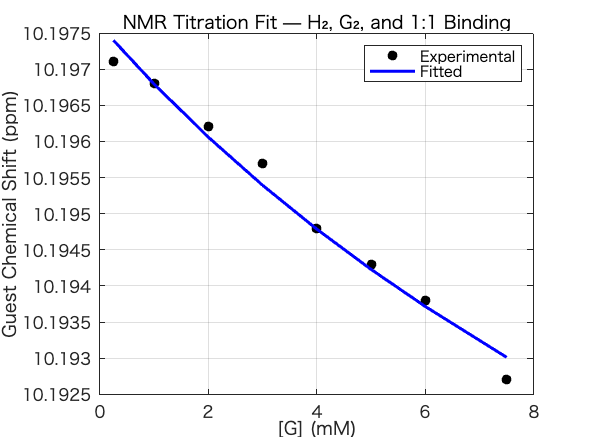


%% === PLOT ===
delta_fit = model_shift(params_fit, [Htot Gtot], KH2, KG2);

figure;
plot(Gtot*1e3, delta_obs_exp, 'ko', 'MarkerFaceColor', 'k'); hold on;
plot(Gtot*1e3, delta_fit, 'b-', 'LineWidth', 2);
xlabel('[G] (mM)'); ylabel('Guest Chemical Shift (ppm)');
legend('Experimental','Fitted');
title('NMR Titration Fit — H₂, G₂, and 1:1 Binding');
grid on;


% Calculate R-squared
SS_res = sum((delta_obs_exp - delta_fit).^2);
SS_tot = sum((delta_obs_exp - mean(delta_obs_exp)).^2);
R_squared = 1 - (SS_res / SS_tot);

% Display R-squared
fprintf('R-squared: %.6f\n', R_squared);

R-squared: 0.981087



%% === FRACTION TABLE AND ERROR CALCULATION ===
fprintf('\n=== Species Fractions and Fitting Error ===\n');


=== Species Fractions and Fitting Error ===


fprintf('  [G]_tot (mM)   delta_obs   delta_fit   Error(ppm)   G_frac   G2_frac   HG_frac\n');

  [G]_tot (mM)   delta_obs   delta_fit   Error(ppm)   G_frac   G2_frac   HG_frac


fprintf('-------------------------------------------------------------------------------\n');

-------------------------------------------------------------------------------



for i = 1:length(Gtot)
    Ht = Htot(i);
    Gt = Gtot(i);

    x0 = [Ht/2, Gt/2, 1e-6, 1e-6, 1e-6];
    sol = fsolve(@(x) system_eqs(x, Ht, Gt, KH2, KG2, KHG), x0, ...
        optimoptions('fsolve','Display','off','TolFun',1e-12,'TolX',1e-12));

    H = sol(1); G = sol(2); HG = sol(3); H2 = sol(4); G2 = sol(5);

    total_guest_species = G + 2*G2 + HG;

    G_frac  = G  / total_guest_species;
    G2_frac = 2*G2 / total_guest_species;
    HG_frac = HG / total_guest_species;

    fprintf('%10.3f     %9.5f   %9.5f    %9.6f   %7.3f   %7.3f   %7.4f\n', ...
        Gt*1e3, delta_obs_exp(i), delta_fit(i), (delta_obs_exp(i) - delta_fit(i)), ...
        G_frac, G2_frac, HG_frac);
end

     0.250      10.19710    10.19740    -0.000301     0.992     0.007    0.0004
     1.000      10.19680    10.19679     0.000005     0.971     0.028    0.0004
     2.000      10.19620    10.19606     0.000141     0.946     0.054    0.0004
     3.000      10.19570    10.19539     0.000307     0.923     0.077    0.0004
     4.000      10.19480    10.19479     0.000014     0.901     0.098    0.0003
     5.000      10.19430    10.19423     0.000071     0.882     0.118    0.0003
     6.000      10.19380    10.19371     0.000085     0.864     0.135    0.0003
     7.500      10.19270    10.19301    -0.000311     0.840     0.160    0.0003


function delta_obs = model_shift(params, xdata, KH2, KG2)
    KHG = 10^params(1); % 1:1 binding constant
    delta_G  = params(2);
    delta_G2 = params(3);
    delta_HG = params(4);

    Htot = xdata(:,1);
    Gtot = xdata(:,2);
    N = length(Htot);
    delta_obs = zeros(N,1);

    for i = 1:N
        Ht = Htot(i);
        Gt = Gtot(i);

        % Initial guesses for [H, G, HG, H2, G2]
        x0 = [Ht/2, Gt/2, 1e-6, 1e-6, 1e-6];

        sol = fsolve(@(x) system_eqs(x, Ht, Gt, KH2, KG2, KHG), x0, ...
            optimoptions('fsolve','Display','off','TolFun',1e-12,'TolX',1e-12));

        H = sol(1); G = sol(2); HG = sol(3); H2 = sol(4); G2 = sol(5);

        % Compute guest chemical shift
        total_guest_species = G + 2*G2 + HG;
        weighted_shift = G*delta_G + 2*G2*delta_G2 + HG*delta_HG;

        delta_obs(i) = weighted_shift / total_guest_species;
    end
end

function F = system_eqs(x, Htot, Gtot, KH2, KG2, KHG)
    % Variables
    H  = x(1); 
    G  = x(2); 
    HG = x(3);
    H2 = x(4); 
    G2 = x(5);

    % Equilibrium relationships
    F(1) = H2 - KH2 * H^2;
    F(2) = G2 - KG2 * G^2;
    F(3) = HG - KHG * H * G;

    % Mass balances
    F(4) = Htot - (H + 2*H2 + HG);
    F(5) = Gtot - (G + 2*G2 + HG);
end
